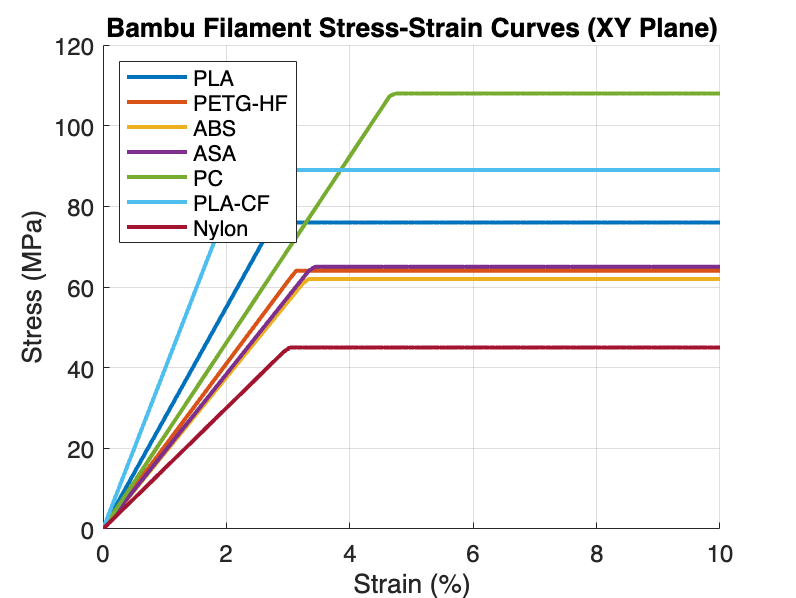

%% Polymer Bearing - Advanced Stress Analysis for 3D Printed Bearings
clear; clc; close all;

%% --- Material Definitions (Bambu Filament Properties) ---
materials = {'PLA', 'PETG-HF', 'ABS', 'ASA', 'PC', 'PLA-CF', 'Nylon'};

% From your images (converted to SI units)
E = [2750, 2050, 1880, 1920, 2310, 3950, 1500] * 1e6;   % Bending Modulus [Pa]
sigma_y = [76, 64, 62, 65, 108, 89, 45] * 1e6;          % Bending Strength [Pa]
nu = [0.36, 0.38, 0.39, 0.38, 0.37, 0.35, 0.40];        % Poisson's Ratio (estimated)
impact_xy = [26.6, 31.5, 39.3, 4.0, 34.6, 23.2, 35.0];  % Impact Strength [kJ/m²]

%% --- Stress-Strain Curves (Elastic-Plastic) ---
figure; 
colors = lines(length(materials));
hold on;
for i = 1:length(materials)
    strain = linspace(0, 0.1, 100); % Up to 10% strain
    stress = E(i) * strain .* (strain <= sigma_y(i)/E(i)) + ...
             sigma_y(i) * (strain > sigma_y(i)/E(i)); % Bilinear approximation
    plot(strain*100, stress/1e6, 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', materials{i});  % Only material name here
end
xlabel('Strain (%)'); 
ylabel('Stress (MPa)');
title('Bambu Filament Stress-Strain Curves (XY Plane)');
legend('Location', 'northwest'); 
grid on;
set(gca, 'FontSize', 12);


%% --- Non-Linear Hertzian Contact Analysis per Material ---
fprintf('\n=== Hertzian Contact Analysis ===\n');


=== Hertzian Contact Analysis ===


F = 200000; % Point load on single ball [N]
R_ball = 3.175e-3/2; % Ball radius [m] (assuming 3.175mm diameter)
E_steel = 210e9;
nu_steel = 0.3;

for i = 1:length(materials)
    % Effective modulus (ball = steel, raceway = polymer)
    E_star = 1 / ((1-nu_steel^2)/E_steel + (1-nu(i)^2)/E(i));
    
    % Contact radius and max pressure for single load F
    a = ((3 * F * R_ball) / (4 * E_star))^(1/3);
    P_max = 3 * F / (2 * pi * a^2);
    
    % Yield safety check
    safety_factor = sigma_y(i) / P_max;
    
    fprintf('%s:\n', materials{i});
    fprintf('  Contact radius = %.3f mm\n', a*1000);
    fprintf('  Max pressure = %.1f MPa (Yield = %.1f MPa)\n', P_max/1e6, sigma_y(i)/1e6);
    fprintf('  Safety factor = %.2f\n\n', safety_factor);
end

PLA:


  Contact radius = 4.243 mm


  Max pressure = 5303.6 MPa (Yield = 76.0 MPa)


  Safety factor = 0.01



PETG-HF:


  Contact radius = 4.648 mm


  Max pressure = 4420.1 MPa (Yield = 64.0 MPa)


  Safety factor = 0.01



ABS:


  Contact radius = 4.768 mm


  Max pressure = 4199.6 MPa (Yield = 62.0 MPa)


  Safety factor = 0.01



ASA:


  Contact radius = 4.750 mm


  Max pressure = 4233.0 MPa (Yield = 65.0 MPa)


  Safety factor = 0.02



PC:


  Contact radius = 4.481 mm


  Max pressure = 4754.8 MPa (Yield = 108.0 MPa)


  Safety factor = 0.02



PLA-CF:


  Contact radius = 3.778 mm


  Max pressure = 6689.7 MPa (Yield = 89.0 MPa)


  Safety factor = 0.01



Nylon:


  Contact radius = 5.122 mm


  Max pressure = 3639.8 MPa (Yield = 45.0 MPa)


  Safety factor = 0.01



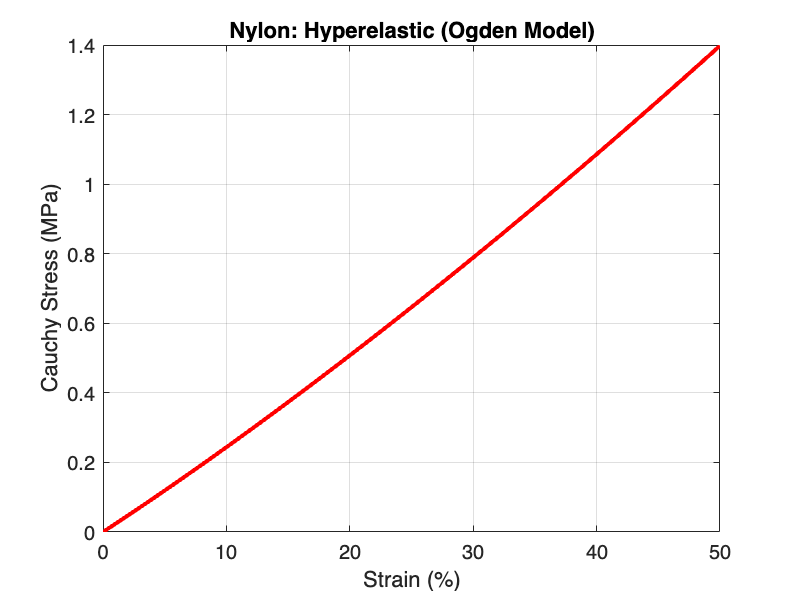


%% --- Hyperelastic Ogden Model (Nylon) ---
lambda = linspace(1, 1.5, 100); mu = [1.5e6, 0.5e6]; alpha = [1.7, -2.0];
stress_hyper = zeros(size(lambda));
for i = 1:length(lambda)
    stress_hyper(i) = sum(mu .* (lambda(i).^alpha - 1./lambda(i).^(alpha/2)));
end

figure;
plot((lambda-1)*100, stress_hyper/1e6, 'r-', 'LineWidth', 2);
xlabel('Strain (%)'); ylabel('Cauchy Stress (MPa)');
title('Nylon: Hyperelastic (Ogden Model)');
grid on;

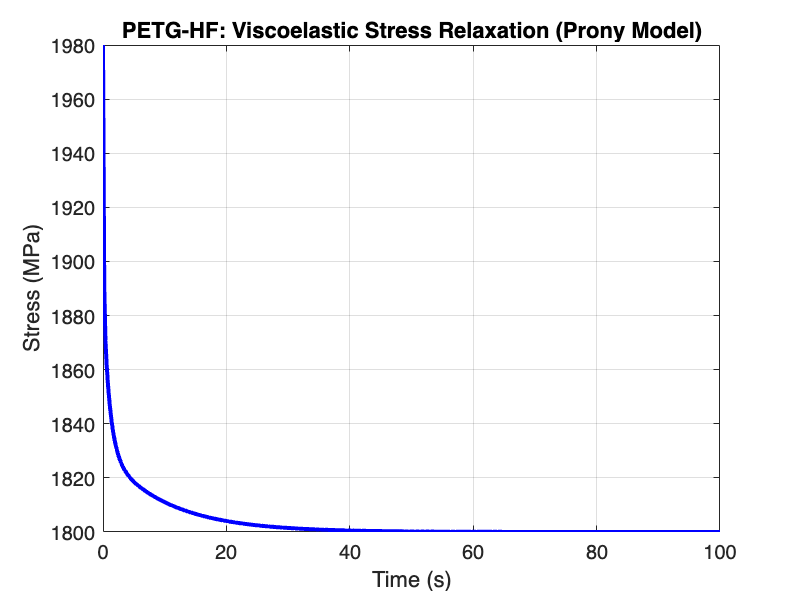


%% --- Viscoelastic Prony Model (PETG-HF) ---
t = linspace(0, 100, 500); E0 = 2.1e9; E_inf = 1.8e9;
tau = [0.1, 1, 10]; weights = [0.3, 0.2, 0.1];
exp_terms = zeros(length(t), length(tau));
for j = 1:length(tau)
    exp_terms(:,j) = weights(j) * exp(-t'/tau(j));  % t' = column vector
end

stress_relax = E_inf + (E0 - E_inf) * sum(exp_terms, 2);
figure;
plot(t, stress_relax/1e6, 'b-', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Stress (MPa)');
title('PETG-HF: Viscoelastic Stress Relaxation (Prony Model)');
grid on;

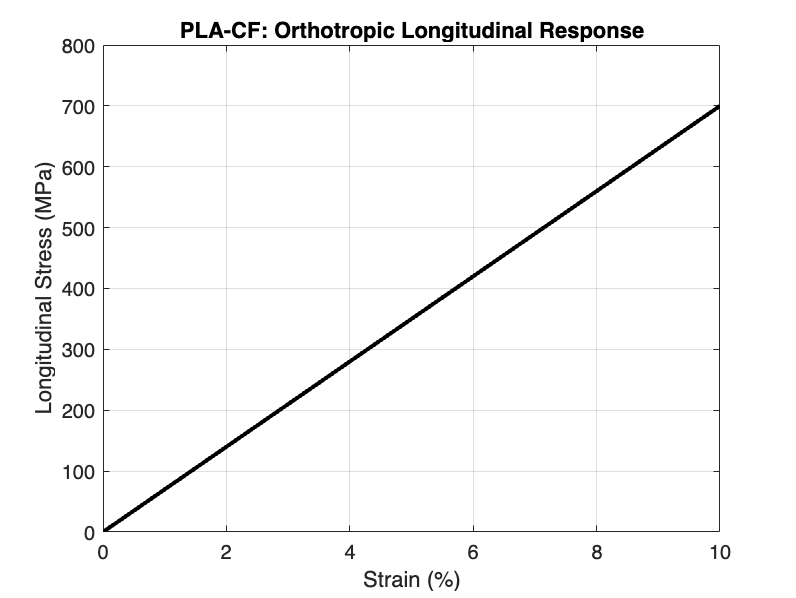


%% --- Orthotropic Model (PLA-CF) ---
E1 = 7e9; E2 = 5e9; G12 = 2e9; nu12 = 0.3;
strain_vals = linspace(0, 0.1, 100);

S = [1/E1, -nu12/E1, 0;
     -nu12/E1, 1/E2, 0;
     0, 0, 1/G12];

stress_ortho = zeros(3, length(strain_vals));
for i = 1:length(strain_vals)
    eps = [strain_vals(i); -nu12*strain_vals(i); 0];
    stress_ortho(:,i) = inv(S) * eps;
end

figure;
plot(strain_vals*100, stress_ortho(1,:)/1e6, 'k-', 'LineWidth', 2);
xlabel('Strain (%)'); ylabel('Longitudinal Stress (MPa)');
title('PLA-CF: Orthotropic Longitudinal Response');
grid on;

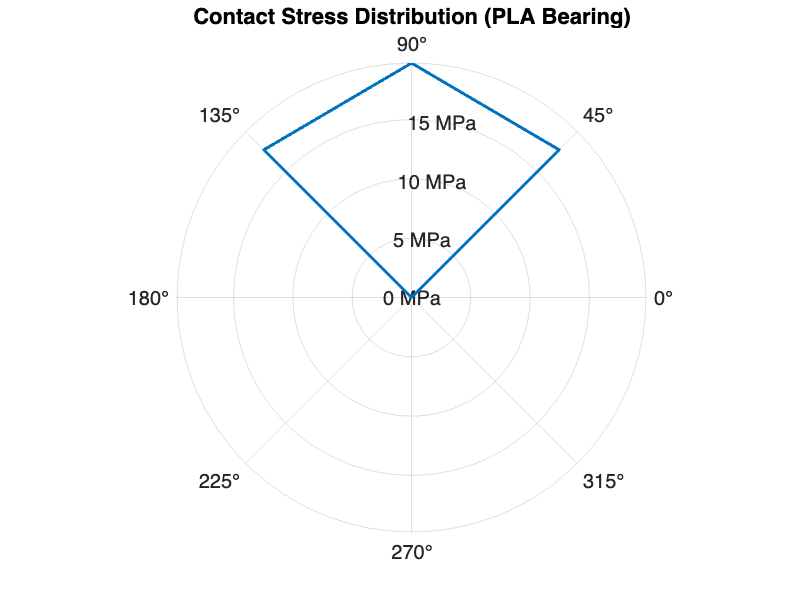

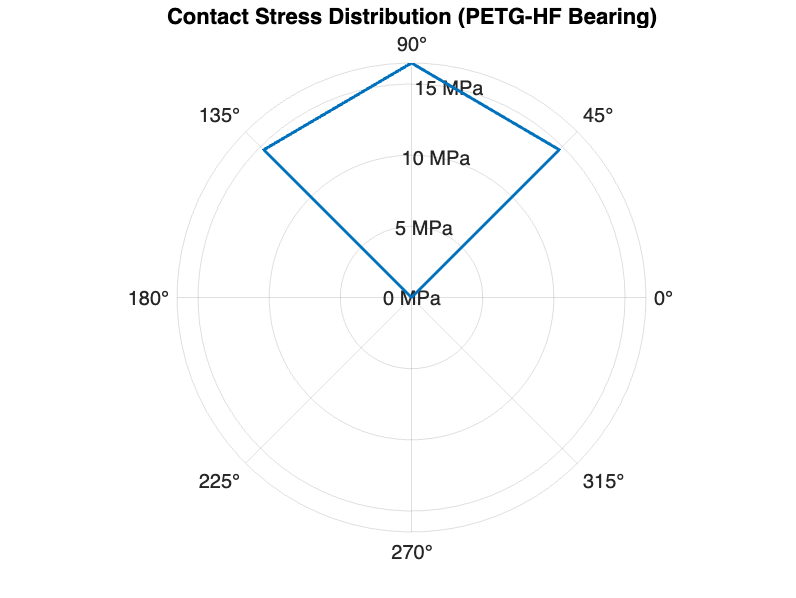

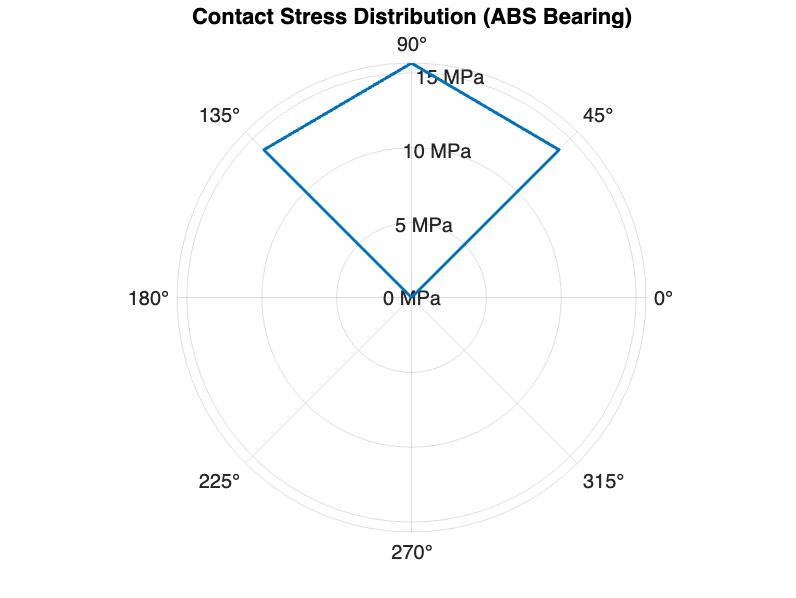

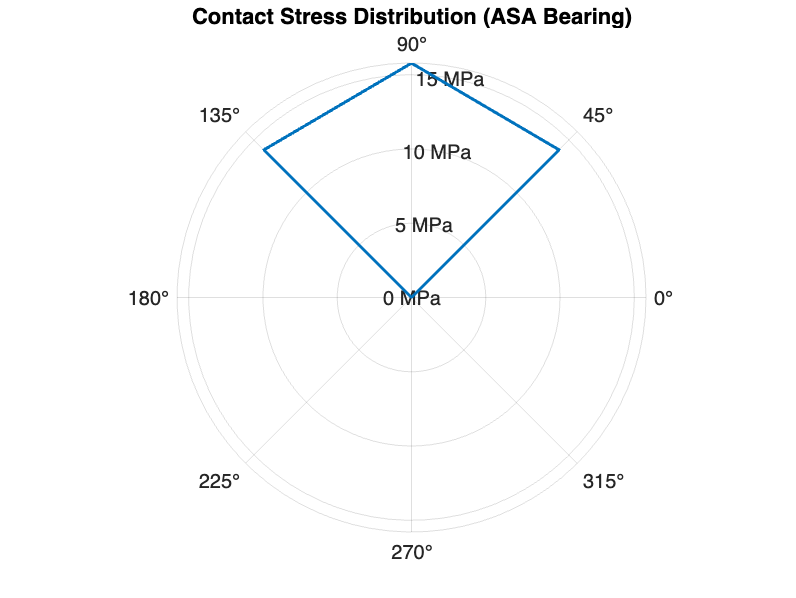

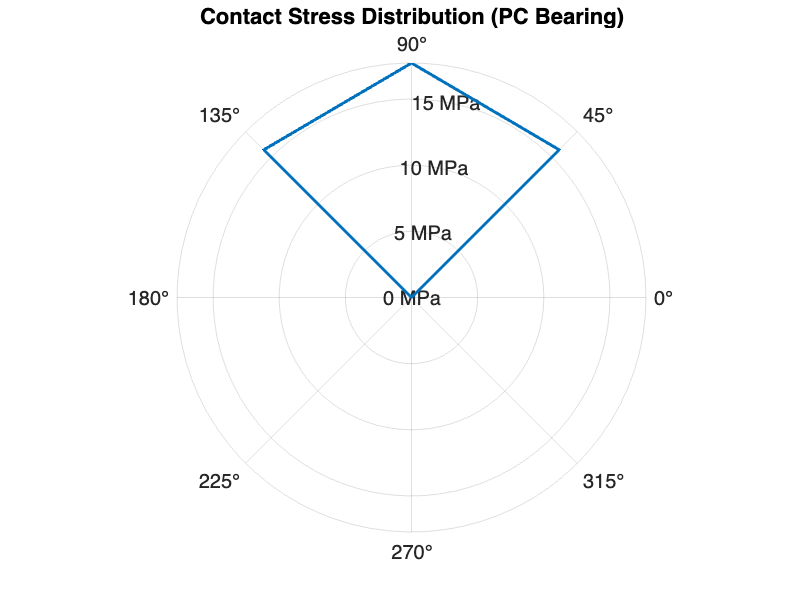

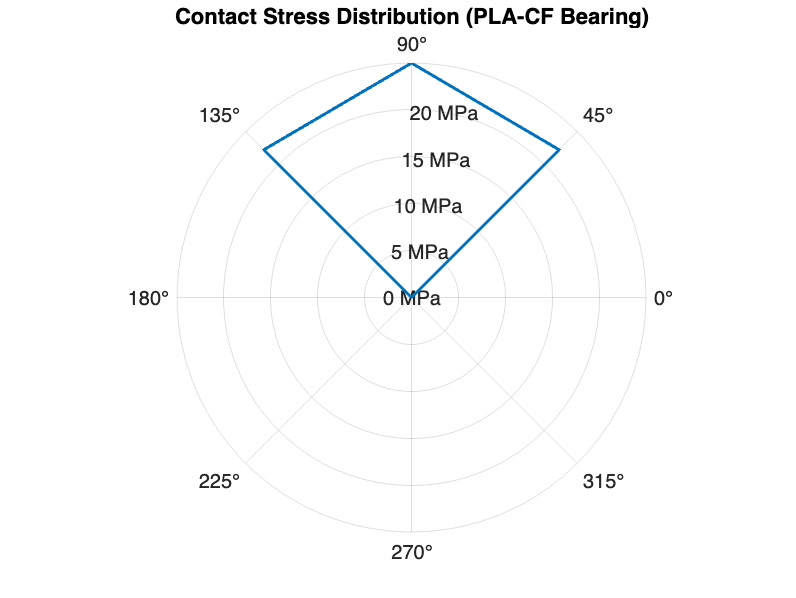

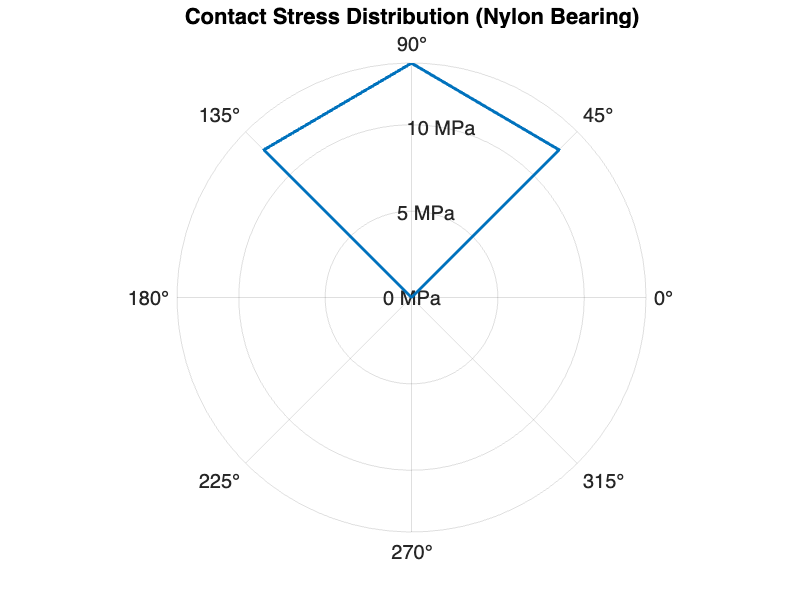


%% --- Load Distribution in 8-Ball Bearing (Consistent Single Load F at 90°) ---
n_balls = 8;
theta = linspace(0, 2*pi, n_balls+1); theta(end) = [];
load_angle = pi/2; % Radial load applied at top (90°)
load_factors = max(cos(theta - load_angle), 0); % Only positive (compressive) loads
load_factors = load_factors / sum(load_factors); % Normalize
Q = F * n_balls * load_factors; % Load per ball [N]

for i = 1:length(materials)
    E_star = 1 / ((1 - nu_steel^2)/E_steel + (1 - nu(i)^2)/E(i)); % Effective modulus per material
    
    sigma_max = zeros(size(Q));
    for k = 1:n_balls
        if Q(k) > 0
            a = ((3 * Q(k) * R_ball) / (4 * E_star))^(1/3);
            sigma_max(k) = 1.5 * Q(k) / (pi * a^2);
        end
    end

    figure;
    polarplot(theta, sigma_max/1e6, 'LineWidth', 1.5);
    title(sprintf('Contact Stress Distribution (%s Bearing)', materials{i}));
    rlim([0 ceil(max(sigma_max/1e6)/5)*5]);
    thetaticks(0:45:315);
    ticks = 0:5:ceil(max(sigma_max/1e6));
    labels = arrayfun(@(x) [num2str(x) ' MPa'], ticks, 'UniformOutput', false);
    rticklabels(labels);
    set(gca, 'FontSize', 10);
end


PLA:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN


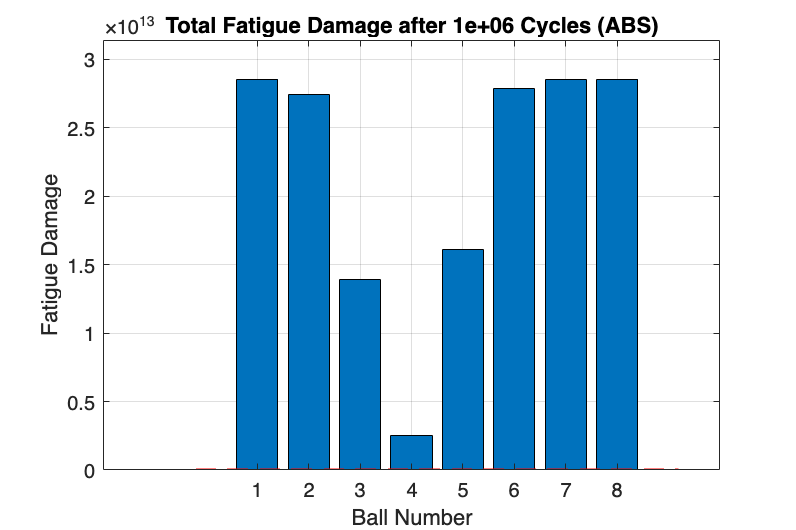


PETG-HF:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN


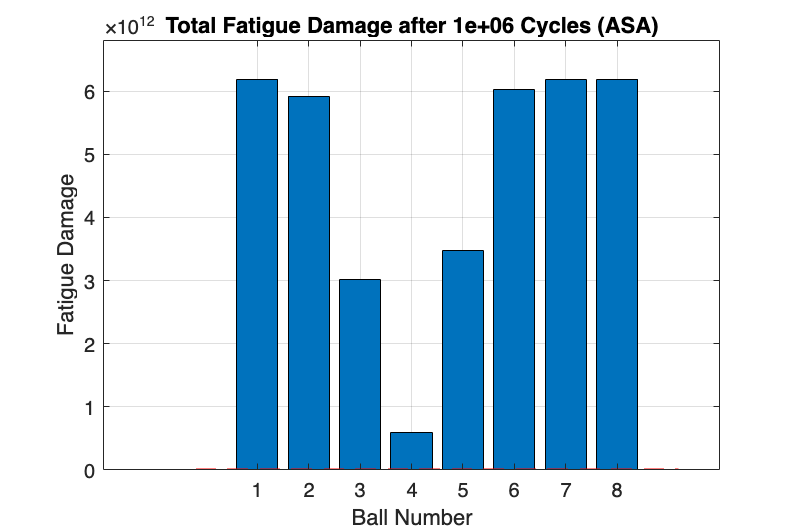


ABS:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN


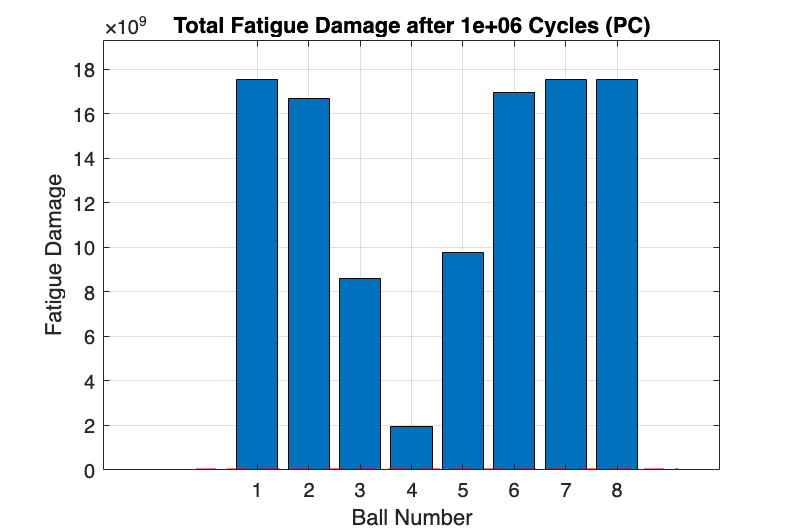


ASA:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN


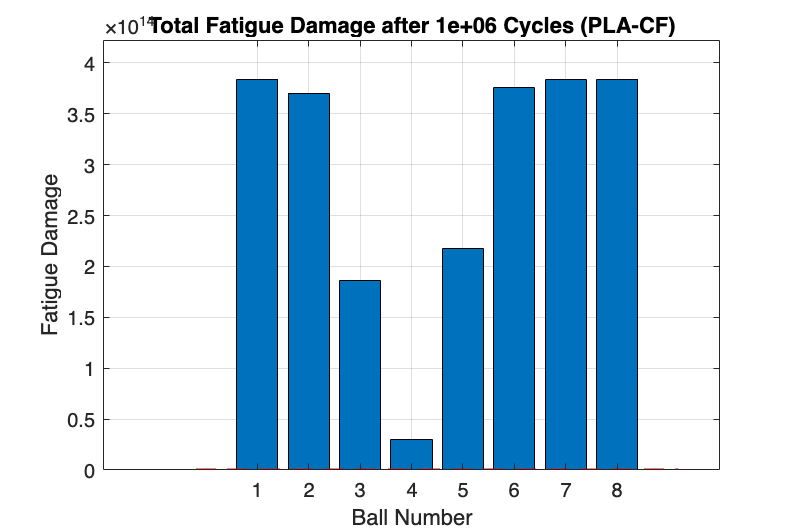


PC:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN


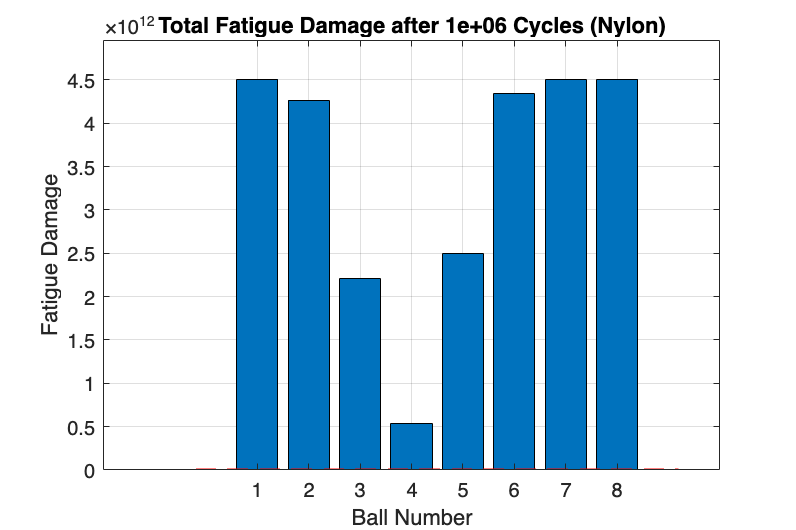


PLA-CF:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN



Nylon:


Equivalent stress: NaN MPa


Fatigue damage after 1000000 cycles: NaN


Reference to a cleared variable Q_cycle.

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

%% Dynamic Polymer Bearing Model (1M Cycles)
clear; clc; close all;

% --- Input Parameters ---
materials = {'PLA', 'PETG-HF', 'ABS', 'ASA', 'PC', 'PLA-CF', 'Nylon'};
E = [2.75, 2.05, 1.88, 1.92, 2.31, 3.95, 1.50] * 1e9; % [Pa]
sigma_y = [76, 64, 62, 65, 108, 89, 45] * 1e6;         % [Pa]
mu = [0.15, 0.18, 0.20, 0.17, 0.12, 0.10, 0.25];       % Friction coeff
k_wear = [2e-7, 3e-7, 5e-7, 4e-7, 1e-7, 8e-8, 6e-7];   % Wear coeff [mm³/Nm]
PV_limit = [0.3, 0.25, 0.2, 0.22, 0.35, 0.4, 0.15];    % [MPa·m/s]

% Operating conditions
F_radial = 100;     % N
RPM = 500;          % Revolutions per minute
n_balls = 8;        % Number of balls
cycles = 1e6;       % Total cycles
ball_d = 3.175e-3;  % Ball diameter [m]

% --- Dynamic Load Distribution ---
theta = linspace(0, 2*pi, n_balls+1); theta(end) = [];
load_angle = pi/2;  % Load at 90°
load_factors = max(cos(theta - load_angle), 0);
load_factors = load_factors / sum(load_factors);
Q = F_radial * load_factors; % Load per ball [N]

% --- Fatigue Life Prediction (Weibull) ---
L10 = zeros(size(materials));
for i = 1:length(materials)
    C = 0.3 * sigma_y(i); % Empirical dynamic capacity
    P_eq = max(Q) * 1.2;  % Equivalent dynamic load (safety factor)
    L10(i) = (C / P_eq)^3 * 1e6 / PV_limit(i); % Adjusted for PV limit
end

% --- Wear Simulation ---
cycles_per_step = 1e5;
n_steps = cycles / cycles_per_step;
wear_volume = zeros(length(materials), n_steps);

for i = 1:length(materials)
    for step = 1:n_steps
        sliding_distance = 2 * pi * ball_d/2 * RPM * cycles_per_step / 60;
        wear_volume(i, step) = k_wear(i) * max(Q) * sliding_distance / (sigma_y(i)/3);
    end
end

% --- Temperature Rise ---
v = RPM * pi * ball_d * 1e-3 / 60; % Sliding velocity [m/s]
cp = 1800; % Specific heat capacity [J/kgK] (average for polymers)
mass = 0.01; % Bearing mass [kg]

delta_T = (mu .* max(Q) .* v * 60) ./ (mass * cp); % Temp rise per minute

% --- Plots for Dissertation ---

% 1. Fatigue Life Comparison
figure;
bar(categorical(materials), L10 / 1e6);
ylabel('Predicted L_{10} Life (Million Cycles)');
title('Fatigue Life of Polymer Bearings (90% Reliability)');
grid on;

% 2. Wear Progression
figure; hold on;
for i = 1:length(materials)
    plot((1:n_steps)*cycles_per_step/1e6, wear_volume(i,:)*1e3, ...
         'LineWidth', 2, 'DisplayName', materials{i});
end
xlabel('Cycles (Millions)'); ylabel('Wear Volume (mm³)');
title('Wear Progression Over 1M Cycles');
legend('Location', 'northwest'); grid on;

% 3. Temperature Effects
figure;
plot(categorical(materials), delta_T, 'ro-', 'LineWidth', 2);
ylabel('Temperature Rise (°C/min)');
title('Frictional Heating at 500 RPM');
grid on;

% 4. Dynamic Load Distribution (Polar Plot)
sigma_max = zeros(size(Q));
for i = 1:n_balls
    E_star = 1 / ((1-0.3^2)/210e9 + (1-0.35^2)/mean(E)); % PLA-CF properties
    a = ((3 * Q(i) * ball_d/2) / (4 * E_star))^(1/3);
    sigma_max(i) = (3 * Q(i)) / (2 * pi * a^2);
end

figure;
polarplot(theta, sigma_max/1e6, 'b-o', 'LineWidth', 1.5);
title('Dynamic Load Distribution (Max Stress = %.1f MPa)', max(sigma_max/1e6));
rlim([0 ceil(max(sigma_max/1e6)/5)*5]);
thetaticks(0:45:315);
rticklabels(arrayfun(@(x) sprintf('%d MPa', x), 0:5:ceil(max(sigma_max/1e6))), 'UniformOutput', false));